# Linear Regression

clear; clc;

load accidents;

## Data Processing

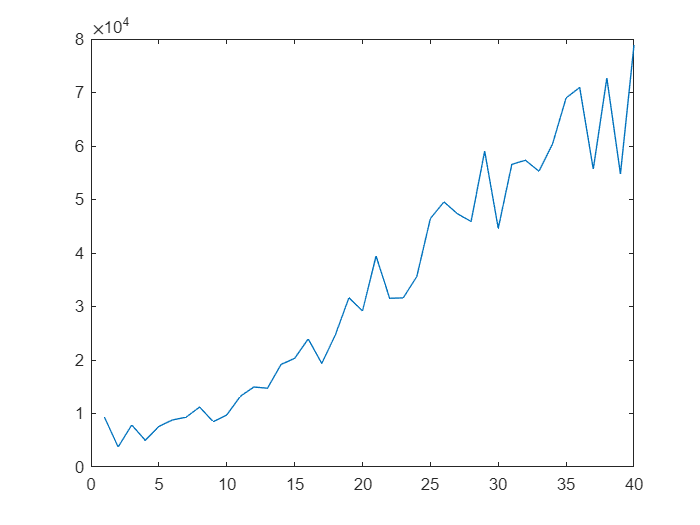

% Vehicle miles | Population
X = [hwydata(:,7) hwydata(:,14)];
% Number of Fatalities | Fatalities with High Blood Alcohol
T = [hwydata(:,4) hwydata(:,12)];

% Test-Train Split
split = 40;
X_train = X(1:split,:);
X_test = X(split+1:end,:);
T_train = T(1:split,:);
T_test = T(split+1:end,:);
train_x = 1:split;

plot(train_x, X_train(:,1))

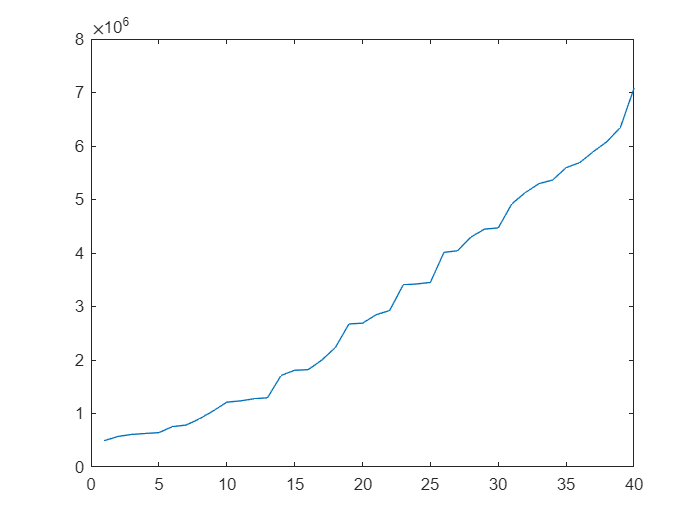

plot(train_x, X_train(:,2))

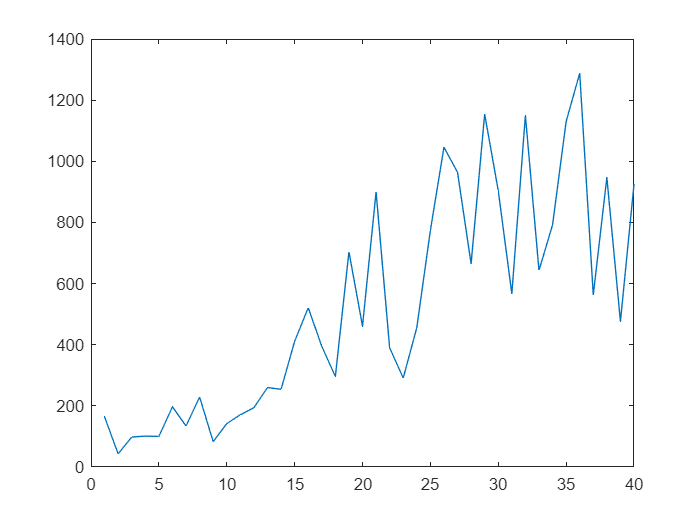

plot(train_x, T_train(:,1))

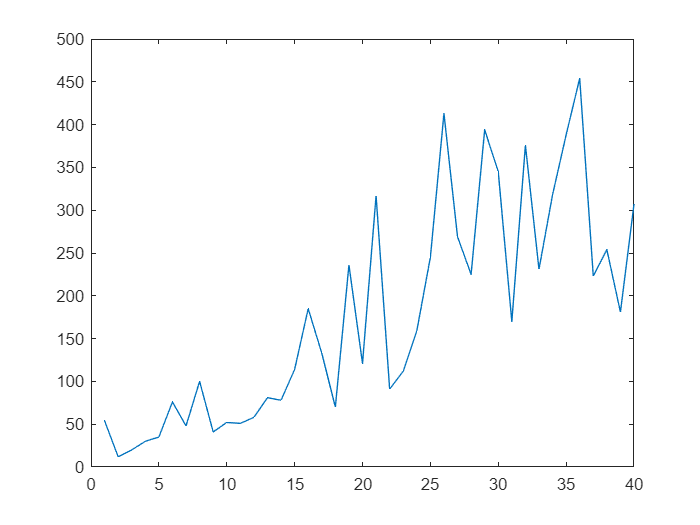

plot(train_x, T_train(:,2))

## Formulation

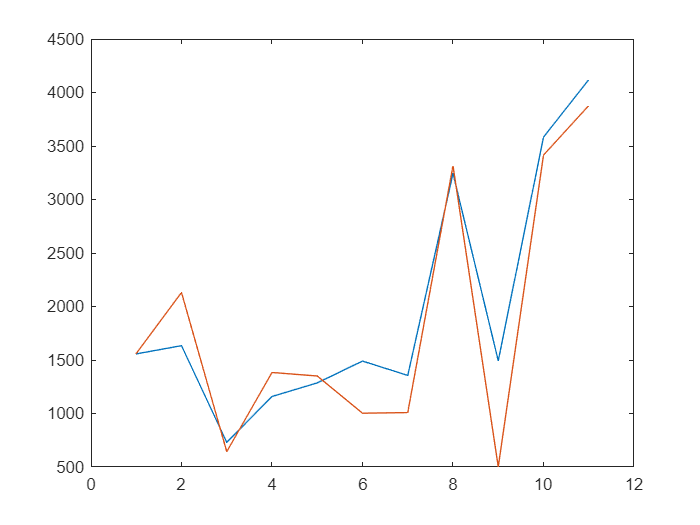

% Assuming Phi(X_n) = X_n
W = ((X_train'*X_train)\X_train')*T_train;
T_pred = (W'*X_test')';
test_x = 1:size(T_test,1);

plot(test_x, T_test(:,1))
hold on;
plot(test_x, T_pred(:,1))
hold off;

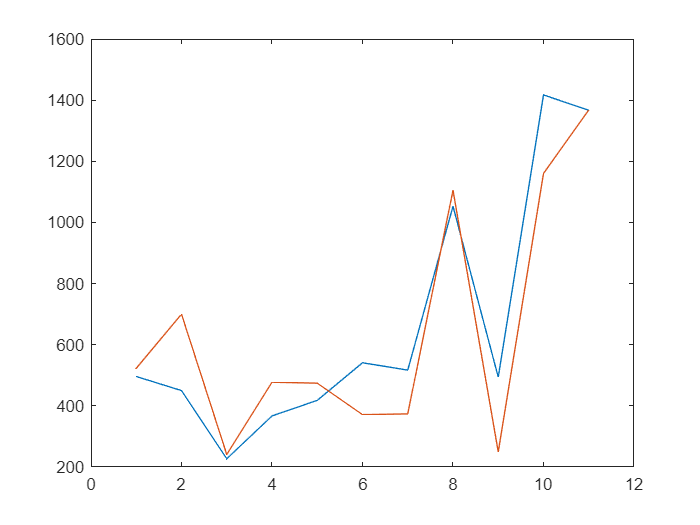

plot(test_x, T_test(:,2))
hold on;
plot(test_x, T_pred(:,2))

Error = T_test-T_pred;
RMSD = [sqrt(mean(Error(:,1).^2)) sqrt(mean(Error(:,2).^2))]

RMSD =   398.0840  152.7677
